# Hexapod simulation

## Create maze

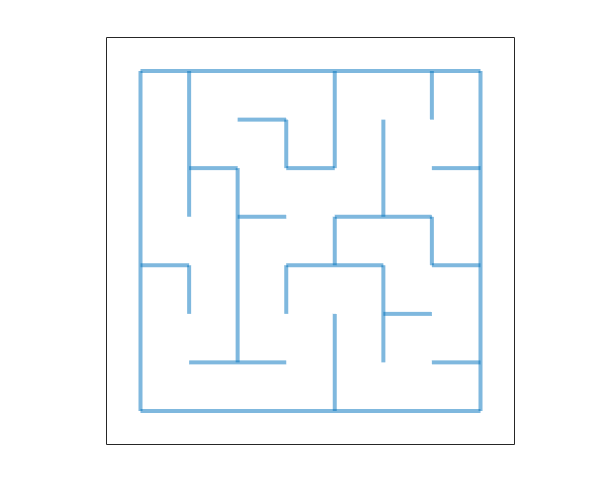

branching = 8;
mazeCreator(branching,'middle',false,false);
pad = 24;
maze = getframe(gca).cdata(pad:end-pad,pad:end-pad,1);

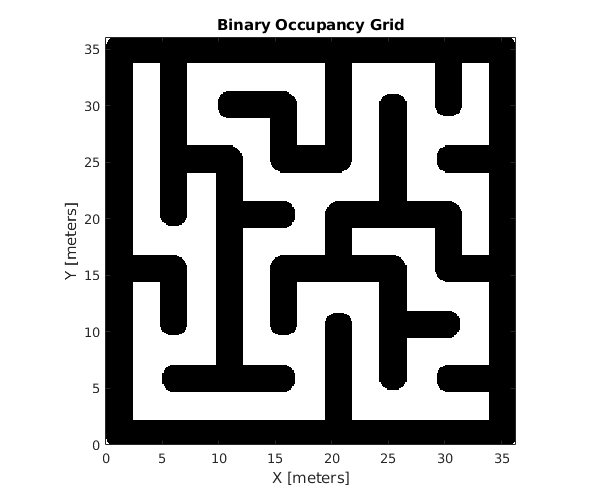

%turn maze into occupancy grid
maze = imbinarize(maze);
maze = imcomplement(maze);
res = 10;
map = binaryOccupancyMap(maze, res);

robotBoundingRadius = 1;
map.inflate(robotBoundingRadius);
show(map)

## Setup state space and planner

%SE(2) state space - rotation not relevant
ss = stateSpaceSE2;
ss.StateBounds = [map.XLocalLimits; map.YLocalLimits; -pi pi];
validator = validatorOccupancyMap(ss);
validator.Map = map;

%RRT* planner
planner = plannerRRTStar(ss,validator);
planner.MaxIterations=1e6;
planner.MaxNumTreeNodes=1e6;
planner.MaxConnectionDistance = 0.7;

 

## Plan path

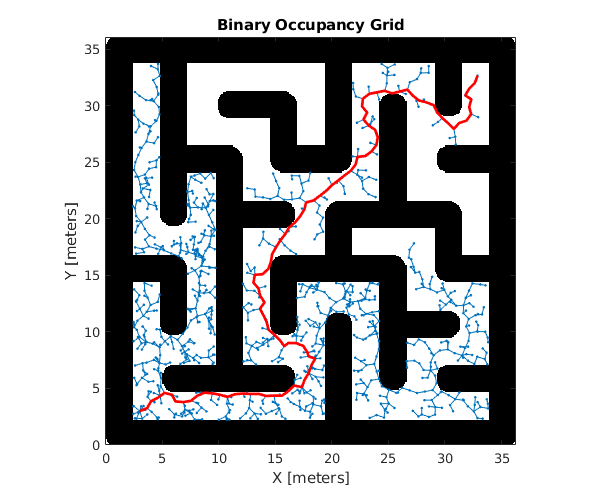

startPose = [3 3 0]; 
goalPose = [33 33 0];

[refpath, solnInfo] = plan(planner, startPose, goalPose);
map.show;
hold on;
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-'); % tree expansion
plot(refpath.States(:,1),refpath.States(:,2),'r-','LineWidth',2); % draw path

wpts = refpath.States;
%trapezoidal velocity profile
tpts = 0:6; % ti
tvec = 0:0.05:6;
n = size(wpts, 1); % dimensions of trajectory
p = size(wpts, 2); % number of waypoints

Ts = 0.1;
[q,qd,qdd,t,pp] = trapveltraj(wpts', length(tvec), 'EndTime',  tpts(end));
%running simulation
open_system('hexapod_LC')
Tf = 10;
simout = sim('hexapod_LC', [0 Tf]);

 

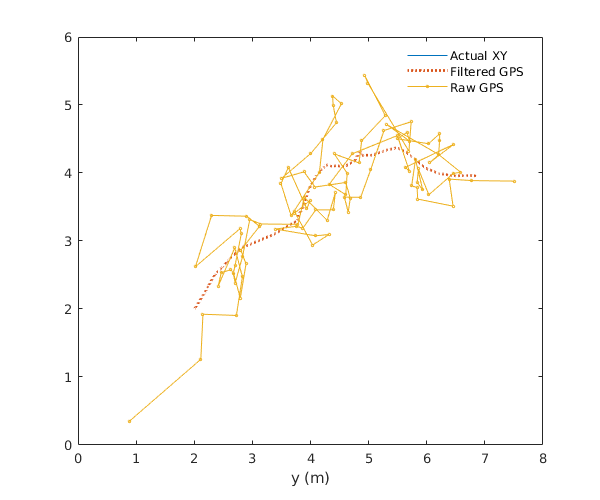

[ state, state_KF, state_GPS] = extractSimOutHelper(simout, Tf);
%plotting final path
plotPathHelper(state, state_KF, state_GPS)

function [time, state, stateDot] = extractSimOutHelper(simout, Tf)
time = linspace(0, Tf, length(simout.yout{1}.Values.Data(:,1)));
state = simout.yout{1}.Values.Data;
stateDot = simout.yout{2}.Values.Data;
end

function plotHelperFunction(startPose, waypoints, state, stateDot)
res = 5; 
v = sqrt(stateDot(:,1).^2 + stateDot(:,2).^2);

scatter(state(1:res:end,1), state(1:res:end,2), 20, v(1:res:end), "filled","s","MarkerEdgeColor",'k'), hold on, 

% start pose
scatter(startPose(1), startPose(2), 80, "red",   "filled","MarkerEdgeColor",'k')

% end pose
scatter(state(end,1),  state(end,2) , 120, "green", "filled","x","MarkerEdgeColor",'k')

% goal pose
cmap = jet(size(waypoints,1));
for i = 1:size(waypoints,1)
    scatter(waypoints(i,1),  waypoints(i,2) , 80, cmap(i,:), "filled","MarkerEdgeColor",'k')
end

end
function dist = distance(x1,y1,x2,y2)
    dist=sqrt((x1-x2)^2 + (y1-y2)^2);
end
function plotPathHelper(state, state_KF, state_GPS)

figure, hold on
plot(state(:,1), state(:,2))
plot(state_KF(:,1), state_KF(:,2),':', 'linewidth',2)
plot(state_GPS(:,1), state_GPS(:,2), 'o-','markersize',2)
box on
legend('Actual XY', 'Filtered GPS', 'Raw GPS')
legend box off
xlabel 'x (m)'
xlabel 'y (m)'
legend location best

end